# JeCSon - JERICCO Communications Simulation

### Part I: Data Movement Simulation

clear;clc;close all;

dt = 10; %[sec]
T = linspace(0,100,11); %[sec]
Data_Storage.Total_Storage = 1000; %[Gb]
Data_Storage.Ava_Storage = 800; %[Gb]
Data_Storage.Telemetry_TX = 250; %[Mb/s]
Data_Storage.Payload_TX = 250; %[Mb/s]
Data_Storage.Command_RX = 50; %[Mb/s]
Data_Storage.Telemetry_Gen = 10; %[Mb/s]
Data_Storage.Payload_Gen = 10; %[Mb/s]

A = [Data_Storage.Ava_Storage];
for i=2:size(T,2)
    Data_Storage = Jeri_Comms_Data(dt, Data_Storage);
    A(end+1) = Data_Storage.Ava_Storage;
    Data_Storage.Telemetry_Gen = Data_Storage.Telemetry_Gen + 20;
    Data_Storage.Telemetry_TX = Data_Storage.Telemetry_TX - 50;
end

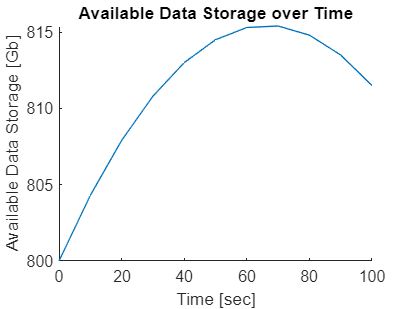

figure;
hold on;
plot(T,A)
title('Available Data Storage over Time');
xlabel('Time [sec]');
ylabel('Available Data Storage [Gb]');
hold off;

### Part II: Link Analysis

Comms_Mode = "TX";

Link_Budget.Propagation_Path_Length = 384400; %[km]
Link_Budget.Polarization_Loss = -0.3; %[dB]
Link_Budget.Implementation_Loss = 2; %[dB]
Link_Budget.Required_Eb_over_N0 = 5; %[dB]
Link_Budget.Bit_Error_Rate = 1e-6; % Unused for now

Link_Budget.TX.Frequency = 8.2; %[GHz]
Link_Budget.TX.Data_Rate = 1e8; %[bps]
        
%Transmitter (JERICCO) Specs
Link_Budget.TX.Transmit_Power = 3; %[W]
Link_Budget.TX.Transmit_Line_Loss = -0.5; %[dB]
Link_Budget.TX.Transmit_Antenna_Beamwidth = NaN; %[deg], unused
Link_Budget.TX.Peak_Transmit_Antenna_Gain = 12; %[dBi]
Link_Budget.TX.Transmit_Antenna_Diameter = NaN; %[m], unused
Link_Budget.TX.Transmit_Antenna_Pointing_Offset = NaN; %[deg], unused
Link_Budget.TX.Transmit_Antenna_Pointing_Loss = 0; %[dB]

%Receiver (DSN) Specs
Link_Budget.TX.Receive_Antenna_Diameter = NaN; %[m], unused
Link_Budget.TX.Peak_Receive_Antenna_Gain = 68.2; %[dBi]
Link_Budget.TX.Receive_Antenna_Beamwidth = NaN; %[deg], unused
Link_Budget.TX.Receive_Antenna_Pointing_Error = NaN; %[deg], unused
Link_Budget.TX.Receive_Antenna_Pointing_Loss = 0; %[dB]
Link_Budget.TX.Receive_Antenna_Gain_to_Noise_Temp_Ratio = 54.2; %[dB/K]

Link_Analysis = Jeri_Comms_Link(dt, Link_Budget, Comms_Mode);
fprintf('Equivalent Isotropic Radiated Power: %0.3f[dBW]\n', Link_Analysis.EIRP);

Equivalent Isotropic Radiated Power: 16.271[dBW]


fprintf('Energy/Bit to Noise Density Ratio: %0.3f\n', Link_Analysis.Eb_over_N0);

Energy/Bit to Noise Density Ratio: 9.351


fprintf('Carrier to Noise Density Ratio: %0.3f[dB-Hz]\n', Link_Analysis.C_over_N0);

Carrier to Noise Density Ratio: 89.351[dB-Hz]


fprintf('Available Link Margin: %0.3f[dB]\n', Link_Analysis.Margin);

Available Link Margin: 2.351[dB]
